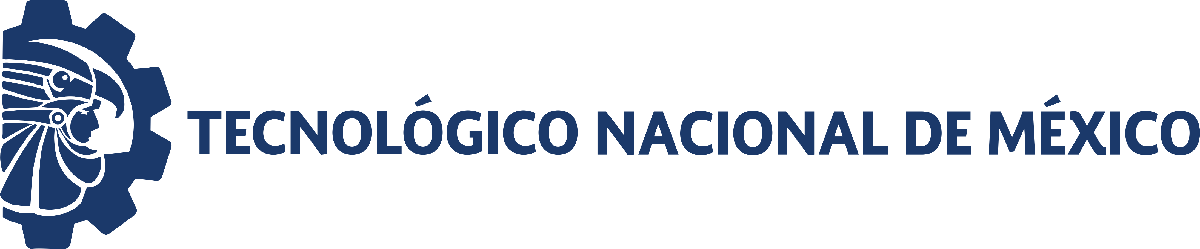                                 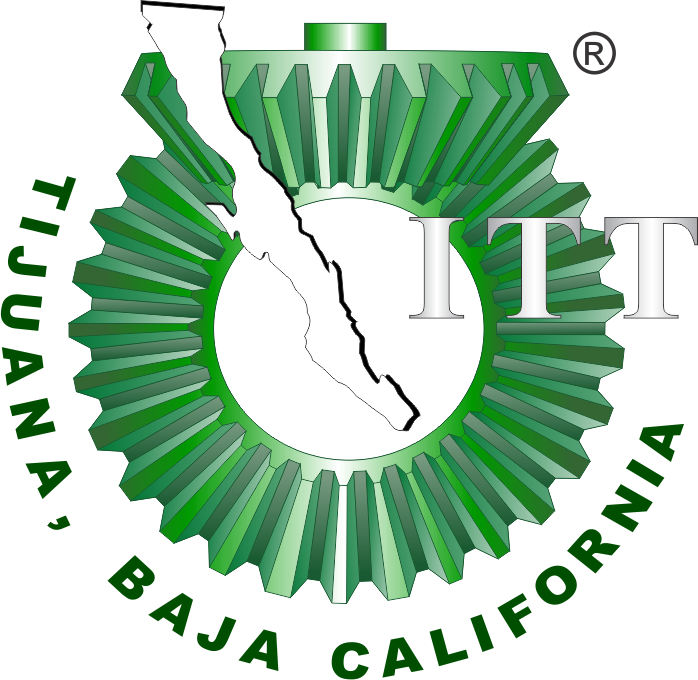

# Práctica 4: Sistema Sanguíneo 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

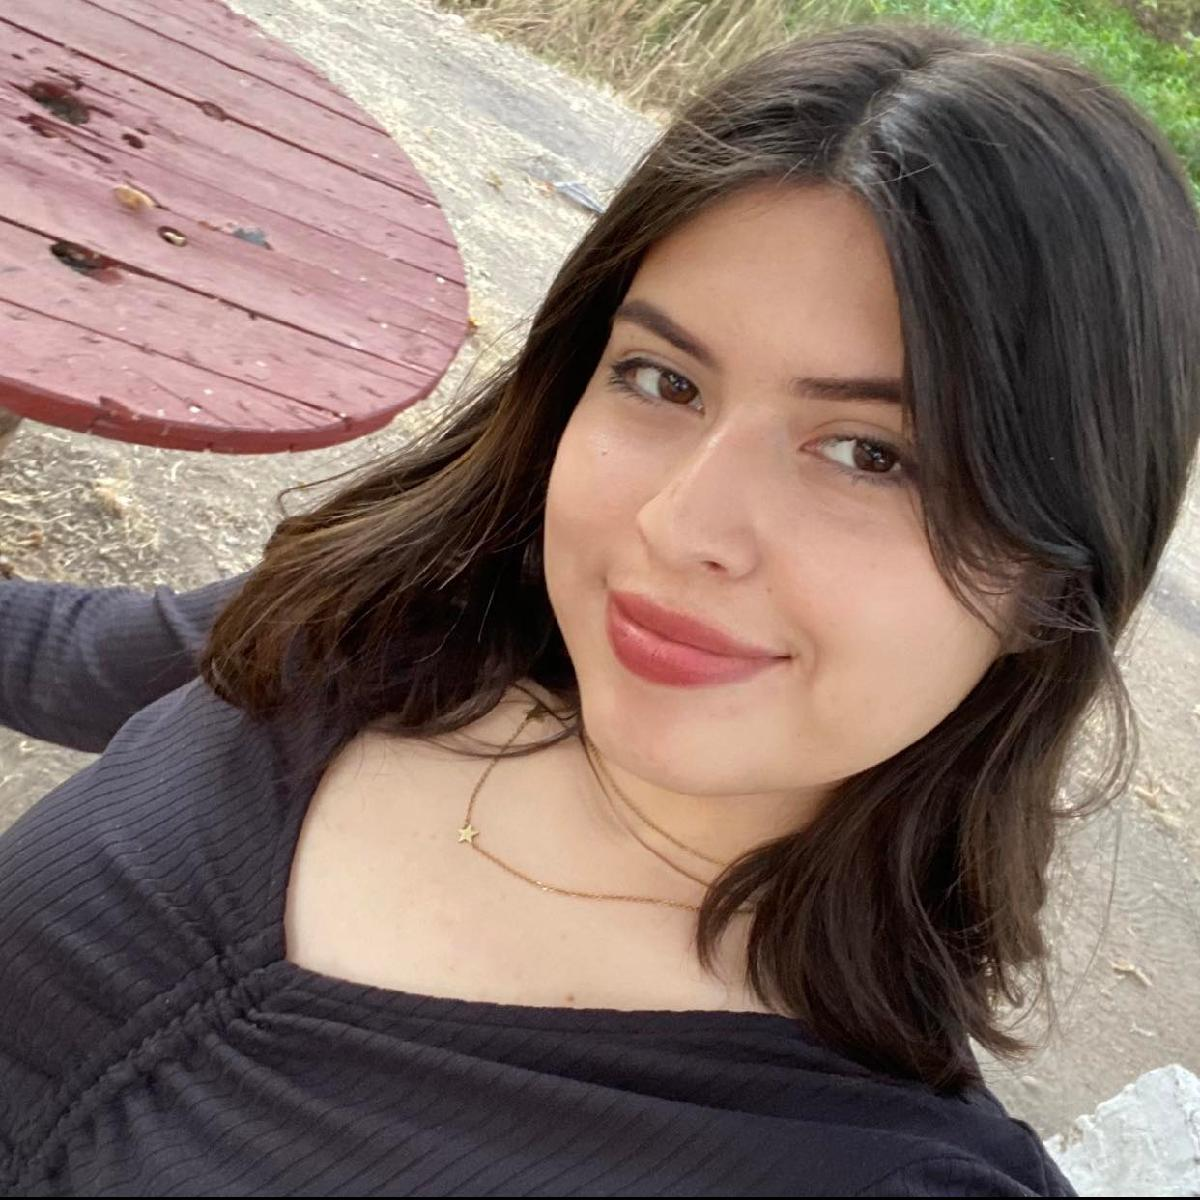

Nombre del alumno: **Lugo Valenzuela Liliana Fernanda**

Número de control: **21212165**

Correo institucional: **L21212165@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short ; warning('off','all')
tend = 180; %tiempo de la simulacion en dias 
dt = 1E-3; %intervalo de integración para el mpetodo de solución por diferencias finitas 
n = round(tend/dt); %cantidad de iterqaciones para el método numperico 

%condiciones inciiales base para cada paciente 
x1_0 = 59; x2_0 = 44; x3_0 = 885; 

%parámetros partoculares para cada paciente 
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057]; 
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 21212165; 
rng(seed, 'twister')

xmin = 0.99; xmax = 1.01; 
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%condiciones inciiales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');

x1(0) = 
   58.7388   59.3514   59.0490   58.6256   59.3377   59.1521   59.3891   59.1744   58.6649   59.0682



x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');

x2(0) = 
   43.8052   44.2621   44.0365   43.7208   44.2518   44.1134   44.2901   44.1300   43.7501   44.0509



x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x3(0) = 
  881.0817  890.2715  885.7344  879.3845  890.0655  887.2813  890.8358  887.6153  879.9737  886.0231



tend = 180; %tiempo de la simulacion en dias 
dt = 1E-3; %intervalo de integración para el mpetodo de solución por diferencias finitas 
n = round(tend/dt); %cantidad de iterqaciones para el método numerico 
l1 = zeros (1,numel(gamma)); l2 = zeros(1, numel(gamma)); l3 = zeros(1,numel(gamma)); 

## **Caso: Sin transfusión sanguínea **

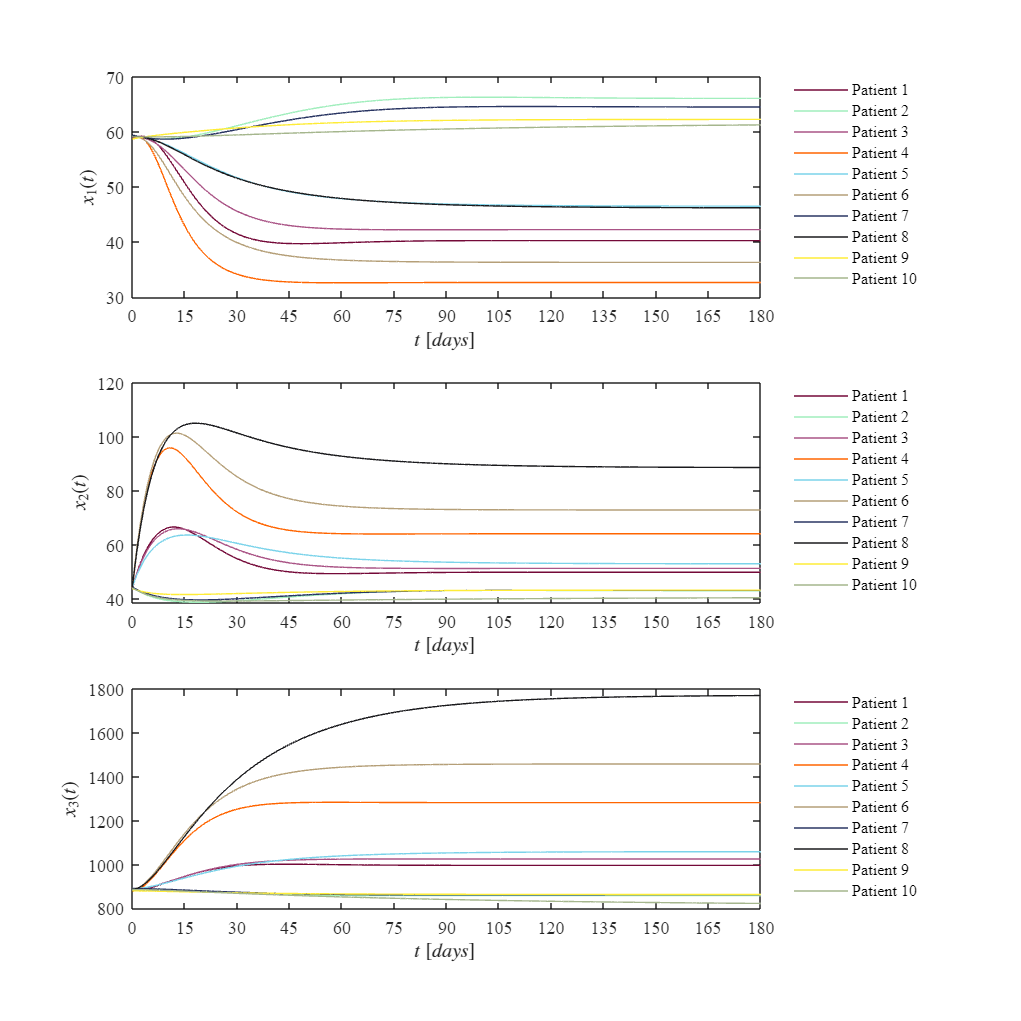

u = zeros(n+1,1); %no hay transfusión
fig = 1; 
    for i = 1:10
        [t,x1,x2,x3]= system(x1_0(i),x2_0(i),x3_0(i),beta(i), gamma(i), u, dt, tend);
        plotdata(t,x1,x2,x3,fig)
    end 

## **Caso: Con transfusión sanguínea**

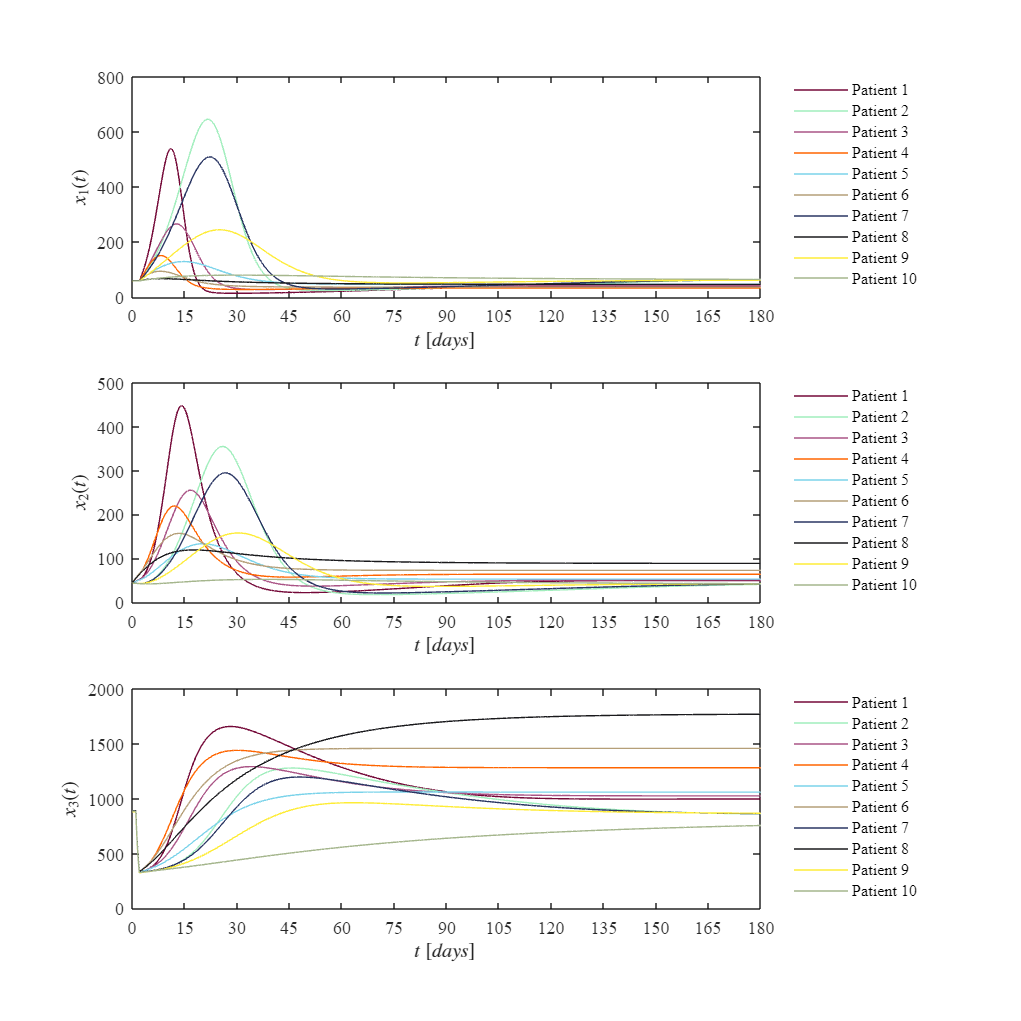

close all;
u(1/dt:2/dt) = 1;
fig = 2; 
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
     l1(i) = x1(end); l2(i) = x2(end); l3 = x3(end);
end 

## **Función: Modelo Matemático**


$$x_1 =\beta \left(X_0 -k_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$x_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$


$x_3$= $\beta \left(k_2 x_2 -a_{\textrm{x3}} \right)-u\left(t\right)x_3$

function [t,x1, x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%parámetros fijos del sistema
Base = 885.42; X0 = 7.3785; k1 = 0.125; k2=0.1667; alpha=0.00833;
t = (0:dt:tend)';
n= round(tend/dt);
x1 = zeros(n+1,1); x1(1) = x1_0;
x2 = zeros(n+1,1); x2(1) = x2_0;
x3 = zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n 
         x1(i+1) = x1(i) + (beta* (X0 - k1*x1(i)) + gamma*(Base-x3(i))*(1-u(i))*x1(i)/Base) * dt; 
         x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i)) * dt; 
         x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end 
end 

## **Función: Soluciones en el tiempo**

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,20])
    mycolors =  [116, 9, 56;       % vino / borgoña oscuro
           161, 238, 189;    % verde menta claro
           170, 84, 134;     % rosa violáceo / fucsia apagado
           255, 101, 0;      
           123, 211, 234;    
           181, 159, 120;   
            42, 54, 99;      
            26, 26, 29;      
           254, 236, 55;   
           165, 182, 141;    
          ] / 255; %colorhunt.co 

    subplot (3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1) 
    xlabel ('$t$ $[days]$ ', 'Interpreter', 'latex', 'FontSize',10)
    ylabel ('$x_1(t)$', 'Interpreter', 'latex', 'FontSize',10)
    xlim([0 180 ]); xticks (0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
        set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)

       subplot (3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2) 
    xlabel ('$t$ $[days]$ ', 'Interpreter', 'latex', 'FontSize',10)
    ylabel ('$x_2(t)$', 'Interpreter', 'latex', 'FontSize',10)
    xlim([0 180 ]); xticks (0:15:180)
     L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
        set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(L,'FontSize',9,'Box', 'Off','Location','NorthEastOutside');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)

        subplot (3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3) 
    xlabel ('$t$ $[days]$ ', 'Interpreter', 'latex', 'FontSize',10)
    ylabel ('$x_3(t)$', 'Interpreter', 'latex', 'FontSize',10)
    xlim([0 180 ]); xticks (0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
        set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)



    if fig == 1 
        exportgraphics(gcf, 'Caso Sin Transfusión.pdf', 'ContentType', 'Vector')
    elseif fig == 2
         exportgraphics(gcf, 'Caso Con Transfusión.pdf', 'ContentType', 'Vector')
    end 
end 



